# OptForce Tutorial

## Sebastián N. Mendoza F.  May 30th, 2017. snmendo@uc.cl

In this tutorial we will run optForce. For a detailed description of the procedure, please see[1]: Ranganathan S, Suthers PF, Maranas CD (2010) OptForce: An Optimization Procedure for Identifying All Genetic Manipulations Leading to Targeted Overproductions. PLOS Computational Biology 6(4): e1000744. https://doi.org/10.1371/journal.pcbi.1000744. 

Briefly, the problem is to find a set of interventions of size "K" such that when these interventions are applied to a wild-type strain, the mutant created will produce a particular target of interest in a higher rate than the wild-type strain. The interventions could be knockouts (lead to zero the flux for a particular reaction), upregulations(increase the flux for a particular reaction) and downregulations (decrease the flux for a particular reaction). 

This prodecure consists on three steps:

1) Perform FVA in both wild type and mutant strains

2) Find the must sets, i.e, reactions that MUST increase or decrease their flux in order to achieve the phenotype in the mutant strain. 

## Figure 1.

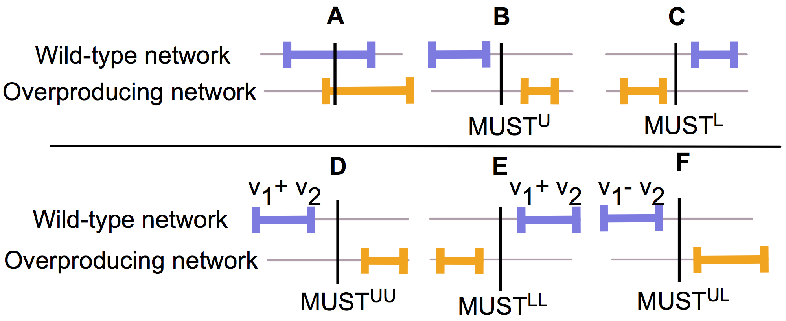

3) Find the interventions needed that will ensure a increased production of the target of interest

For example, imagine that we would like to increase the production of succinate in Escherichia coli. Which are the interventions needed to increase the production of succinate? We will approach this problem in this tutorial and we will see how each of the three steps are solved. 

%initCobraToolbox

Now,  we can start with the modelling

## Modelling

First we load the model. This model comprises only 90 reactions, which describe the central metabolism of E. coli [2].

Then, we change the objective function to maximize biomass ("R75"). We also change the lower bounds, so E. coli will be able to consume glucose, oxygen, sulfate, ammomium, citrate and glycerol. Finally, we change the reversibility flag because these reactions are now reversible

model = []; load('AntCore');
model.c(strcmp(model.rxns,'R75')) = 1;
model = changeRxnBounds(model, 'EX_gluc', -100, 'l'); model.rev(strcmp(model.rxns, 'EX_gluc')) = 1;
model = changeRxnBounds(model, 'EX_o2', -100, 'l'); model.rev(strcmp(model.rxns, 'EX_o2')) = 1;
model = changeRxnBounds(model, 'EX_so4', -100, 'l'); model.rev(strcmp(model.rxns, 'EX_so4')) = 1;
model = changeRxnBounds(model, 'EX_nh3', -100, 'l'); model.rev(strcmp(model.rxns, 'EX_nh3')) = 1;
model = changeRxnBounds(model, 'EX_cit', -100, 'l'); model.rev(strcmp(model.rxns, 'EX_cit')) = 1;
model = changeRxnBounds(model, 'EX_glyc', -100, 'l'); model.rev(strcmp(model.rxns, 'EX_glyc')) = 1;



We define an ID for this run. Each time you run the functions associated to the optForce procedure, some folders will be generated to store inputs and ouputs. These folder will be located in the folder defined in your run ID. Thus if your runID is ''TestOptForce", the structure of the folder will be the following:

`├── CurrentFolder`

`|   ├── TestOptForce`

`|   |   ├── Inputs`

`|   |   └── Outputs`

To avoid the generation of inputs and outputs folders, set keepInputs = 0, printExcel = 0, printText = 0 and keepGamsOutputs = 0

Also, a report of the run is generated each time you run the functions associated to the optForce procedure. So, the idea is to give a different runID each time you run the functions, so you will be able to see the report (inputs used, outputs generated, errors in the run) for each run.

We define then our runID

runID = 'TestOptForce';

## Step 1: Flux Variability Analysis

We run the first step which consist on performing a FVA for both wild-type and mutant strains 

We define constraints for each strain

constrWT = struct('rxnList', {{'R75'}}, 'rxnValues', 14, 'rxnBoundType', 'b');
constrMT = struct('rxnList', {{'R75','EX_suc'}}, 'rxnValues', [0, 155.55], 'rxnBoundType', 'bb');

We  run the FVA analysis for both strains

[minFluxesW, maxFluxesW, minFluxesM, maxFluxesM,~,~] = FVAOptForce(model, constrWT, constrMT);
disp([minFluxesW, maxFluxesW, minFluxesM, maxFluxesM]);

  -90.1251   97.1300   44.4313  100.0000
         0   86.0700   44.4375  100.0000
         0   86.0700   44.4375  100.0000
  -56.1567   86.0700  -44.4500   11.1143
   21.3033  163.5300   55.5500  111.1143
   -3.0777  154.8640   55.5500  111.1143
         0  151.5086         0   55.5625
         0  187.2551         0   55.5687
         0  169.5163         0    0.0187
  -10.0660  102.9449         0    0.0125
   10.0660   66.5714         0    0.0063
  -10.0660  102.9449         0    0.0125
  -48.9454    7.5600   -0.0063         0
  -53.9994    2.5060   -0.0063         0
  -53.9994    2.5060   -0.0063         0
   -2.5060   53.9994         0    0.0063
         0   86.0700         0   55.5625
         0   86.0700         0   55.5625
    9.7020  114.6466   55.5500   55.5625
         0   56.5564   55.5500   55.5571
   16.0264  145.2048  155.5500  155.5563
   16.0264  145.2048  155.5500  155.5563
    0.9344  130.1128  155.5500  155.5562
   -5.6736  123.5048  155.5500  155.5563
         0  118.

Now, the run the second step of OptFoce.

## Step 2: Find Must Sets

Fow now, only functions to find first and second order must sets are supported. As depicted in Fig. 1, the first order must sets are MUSTU and MUSTL; and second order must sets are MUSTUU, MUSTLL and MUSTUL

**A) Finding first order must sets**

We define constraints

constrOpt = struct('rxnList', {{'EX_gluc','R75','EX_suc'}}, 'values', [-100, 0, 155.5]', 'sense', 'EEE');

We then run the functions findMustLWithGAMS.m and findMustUWithGAMS.m that will find mustU and mustL sets, respectively.

Important: To run these function you will need a solver able to solve Mixed Integer Linear Programming (MILP or MIP) problems. Some popular options are: cplex and gurobi. You can see which gams solvers are available in your systems to solve MIP problems by running checkGAMSSolvers('MIP')

We then run findMustL.m and findMustU.m. Here, the following inputs are provided (they are showed by order):

model, minFluxesW, maxFluxesW, constrOpt were defined before. 

runID = ''TestOptForceM' // outputFolder = '' // outputFileName = '' 

printExcel = 1 // printText = 1 // printReport = 1 // keepInputs = 1 // verbose = 0

**i) MustL Set: **

[mustLSet, pos_mustL] = findMustL(model, minFluxesW, maxFluxesW, constrOpt, runID, '', '', 1, 1, 1, 1, 0);

We display the reactions that belongs to the mustL set

disp(mustLSet)

    'R11'
    'R26'
    'R37'
    'R38'
    'R39'
    'R40'
    'R41'
    'R42'
    'R43'
    'R46'
    'R48'
    'R49'
    'R50'
    'R51'
    'R52'
    'R53'
    'R54'
    'R55'
    'R56'
    'R57'
    'R58'
    'R59'
    'R60'
    'R61'
    'R73'
    'R74'
    'PSEUDOpyr_1'
    'PSEUDOpep_1'
    'PSEUDOco2_1'



**ii) MustU set: **

[mustUSet, pos_mustU] = findMustU(model, minFluxesW, maxFluxesW, constrOpt, runID, '', '', 1, 1, 1, 1, 0);

We display the reactions that belongs to the mustU set

disp(mustUSet)

    'R21'
    'R22'
    'R23'
    'R24'
    'R33'
    'R34'
    'R35'
    'R36'
    'R69'
    'EX_pdo'
    'EX_nh3'
    'EX_so4'
    'SUCt'



**B) Finding second order must sets **

First, we define the reactions that will be exluded from the analysis. It it suggested to eliminate reactions found in the previous step as well as exchange reactions

constrOpt = struct('rxnList', {{'EX_gluc', 'R75', 'EX_suc'}}, 'values', [-100, 0, 155.5]', 'sense', 'EEE');
exchangeRxns = model.rxns(cellfun(@isempty, strfind(model.rxns, 'EX_')) == 0);
excludedRxns = unique([mustUSet; mustLSet; exchangeRxns]);

Now, we run the functions for finding second order must sets

**i) MustUU: **

[mustUU, pos_mustUU, mustUU_linear, pos_mustUU_linear] = findMustUU(model, minFluxesW, ...
    maxFluxesW, constrOpt, excludedRxns, runID, '',...
    '', 1, 1, 1, 1, 1);

a MustUU set was found
MustUU set was printed in MustUUSet.xls  
MustUU set was also printed in MustUUSet_Info.xls  
MustUU set was printed in MustUUSet.txt  
MustUU set was also printed in MustUUSet_Info.txt  


We display the reactions that belongs to the mustUU set

disp(mustUU);

    'R30'    'R65'
    'R65'    'R31'



**ii) MustLL: **

[mustLL, pos_mustLL, mustLL_linear, pos_mustLL_linear] = findMustLL(model, minFluxesW, ...
    maxFluxesW, constrOpt, excludedRxns, runID, '',...
    '', 1, 1, 1, 1, 1);

a MustLL set was not found
No mustLL set was not found. Therefore, no excel file was generated
No mustLL set was not found. Therefore, no plain text file was generated


We display the reactions that belongs to the mustLL set. In this case, MustLL is an empty array because no reaction was found in the mustLL set.

disp(mustLL);

**iii) MustUL: **

[mustUL, pos_mustUL, mustUL_linear, pos_mustUL_linear] = findMustUL(model, minFluxesW, ...
    maxFluxesW, constrOpt, excludedRxns, runID, '',...
    '', 1, 1, 1, 1, 1);

a MustUL set was not found
No mustUL set was not found. Therefore, no excel file was generated
No mustUL set was not found. Therefore, no plain text file was generated


We display the reactions that belongs to the mustUL set. In this case, MustUL is an empty array because no reaction was found in the mustUL set.

disp(mustUL);

## Step 3: OptForce

We define constraints and we define "K" the number of interventions allowed, "n_sets" the maximum number of sets to find, and "targetRxn" the reaction producing the metabolite of interest (in this case, succinate). 

Additionally, we define the mustU set as the union of the reactions that must be upregulated in both first order and second order must sets; and mustL set as the union of the reactions that must be downregulated in both first order and second order must sets 

mustU = unique(union(mustUSet, mustUU));
mustL = unique(union(mustLSet, mustLL));
targetRxn = 'EX_suc';
k = 1;
nSets = 1;
constrOpt = struct('rxnList', {{'EX_gluc','R75'}}, 'values', [-100, 0], 'sense', 'EE');
excludedRxns = {};

[optForceSets, posOptForceSets, typeRegOptForceSets, flux_optForceSets] = optForce(model,targetRxn, mustU, mustL, minFluxesW, maxFluxesW, minFluxesM, maxFluxesM, k, nSets, constrOpt, excludedRxns, runID, '', '', 1, 1, 1, 1, 1);

     1


optForce found 1 sets 
Sets found by optForce were printed in OptForce.xls  
Sets found by optForce were printed in OptForce.txt  


We display the reactions found by optForce

disp(optForceSets)

    'EX_suc'



The reaction found was "SUCt", i.e. a transporter for succinate (a very intuitive solution).

Next, we will increase "k" and we will exclude "SUCt" from upregulations to found non-intuitive solutions. We will only search for the 20 best solutions, but you can try with a higher number.

We will change the runID to save both resutls (k = 1 and K = 2) in diffetent folders

k = 2;
nSets = 20;
runID = 'TestOptForceM2';
excludedRxns = struct('rxnList', {{'SUCt'}}, 'typeReg','U');
[optForceSets, posOptForceSets, typeRegOptForceSets, flux_optForceSets] = optForce(model,targetRxn, mustU, mustL, minFluxesW, maxFluxesW, minFluxesM, maxFluxesM, k, nSets, constrOpt, excludedRxns, runID, '', '', 1, 1, 1, 1, 1);

     1


optForce found 1 sets 
Sets found by optForce were printed in OptForce.xls  
Sets found by optForce were printed in OptForce.txt  


We display the reactions found by optForce 

disp(optForceSets)

    'EX_suc'    'R36'



## References

[1] Ranganathan S, Suthers PF, Maranas CD (2010) OptForce: An Optimization Procedure for Identifying All Genetic Manipulations Leading to Targeted Overproductions. PLOS Computational Biology 6(4): e1000744. https://doi.org/10.1371/journal.pcbi.1000744.

[2] Maciek R. Antoniewicz, David F. Kraynie, Lisa A. Laffend, Joanna González-Lergier, Joanne K. Kelleher, Gregory Stephanopoulos, Metabolic flux analysis in a nonstationary system: Fed-batch fermentation of a high yielding strain of E. coli producing 1,3-propanediol, Metabolic Engineering, Volume 9, Issue 3, May 2007, Pages 277-292, ISSN 1096-7176, https://doi.org/10.1016/j.ymben.2007.01.003.